## Signal frequency analysis practice

Convolving with a gaussian filter in time space vs. applying gaussian filter in frequency space and inverse FFT to time space.

Convolution in time domain = element-wise multiplication in frequency space.

Fs = 44100;
T = 5;
t = [0:1/Fs:T];
[yg, Fsg] = audioread("/Applications/MATLAB_R2020b.app/toolbox/audio/samples/RockGuitar-16-96-stereo-72secs.flac");
ygresamp = interp1([0:1/Fsg:(length(yg)-1)/Fsg],yg(:,1),t);

sprate = 10;
sigma = 0.03;
spnoise = saltpeppernoise(sprate,t,Fs);
wnoise = sigma*randn(size(t));

ygnoisy = ygresamp + spnoise + wnoise;

Convolving with Gaussian filter in time domain

W = 13; %window size
sigma = W/6; %for Gaussian filter
gaussianfilter = fspecial('gaussian', [1, W], sigma);
yggaus = conv(ygnoisy, gaussianfilter, 'same');

Apply Gaussian filter in frequency domain

[yfft, f] = myfft(ygnoisy, Fs);
gsigma = 3000;
H = exp(-f.^2/(2*gsigma^2)); %Gaussian filter in frequency space
yfftfilt = yfft'.*H; %Applying the filter in frequency space becomes an elementwise multiplication
yglp = myifft(yfftfilt, f, Fs);

Plot effect of both procedures

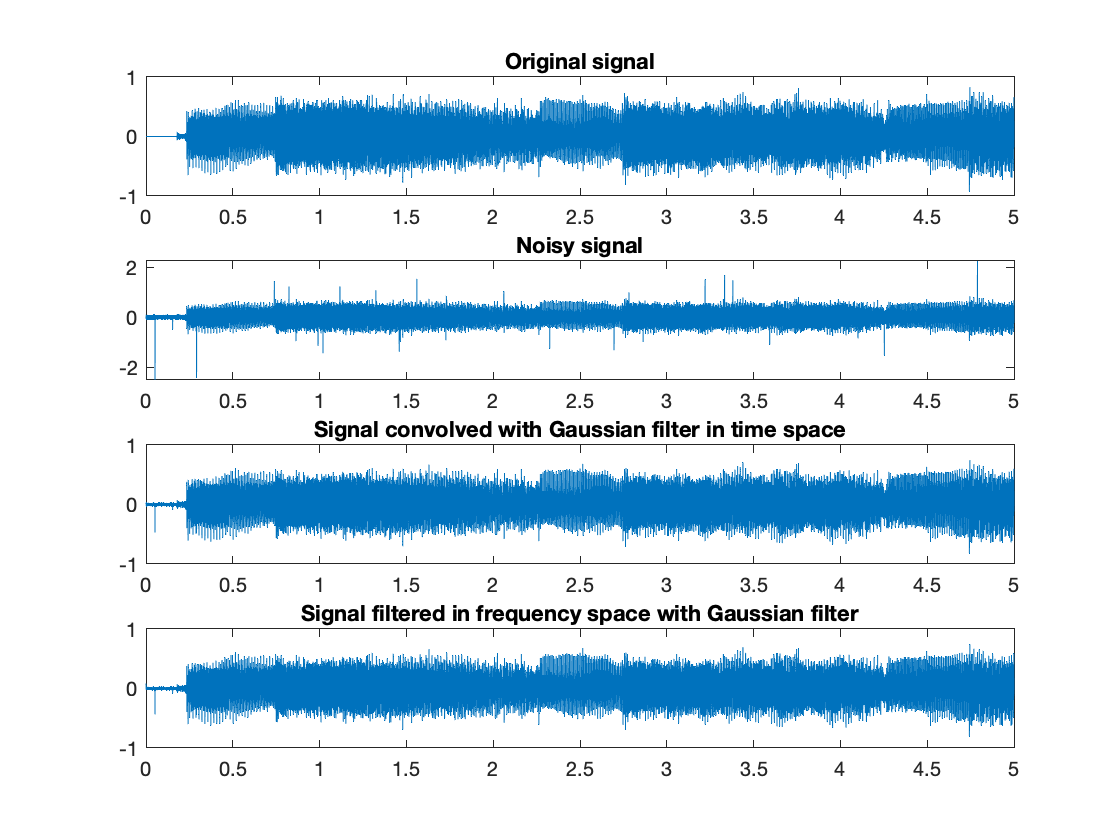

subplot(4, 1, 1)
plot(t, ygresamp)
title('Original signal')

subplot(4, 1, 2)
plot(t, ygnoisy)
title('Noisy signal')

subplot(4, 1, 3)
plot(t, yggaus)
title('Signal convolved with Gaussian filter in time space')

subplot(4, 1, 4)
plot(t, flipud(yglp))
title('Signal filtered in frequency space with Gaussian filter')